# Detect Bottom Rectangle

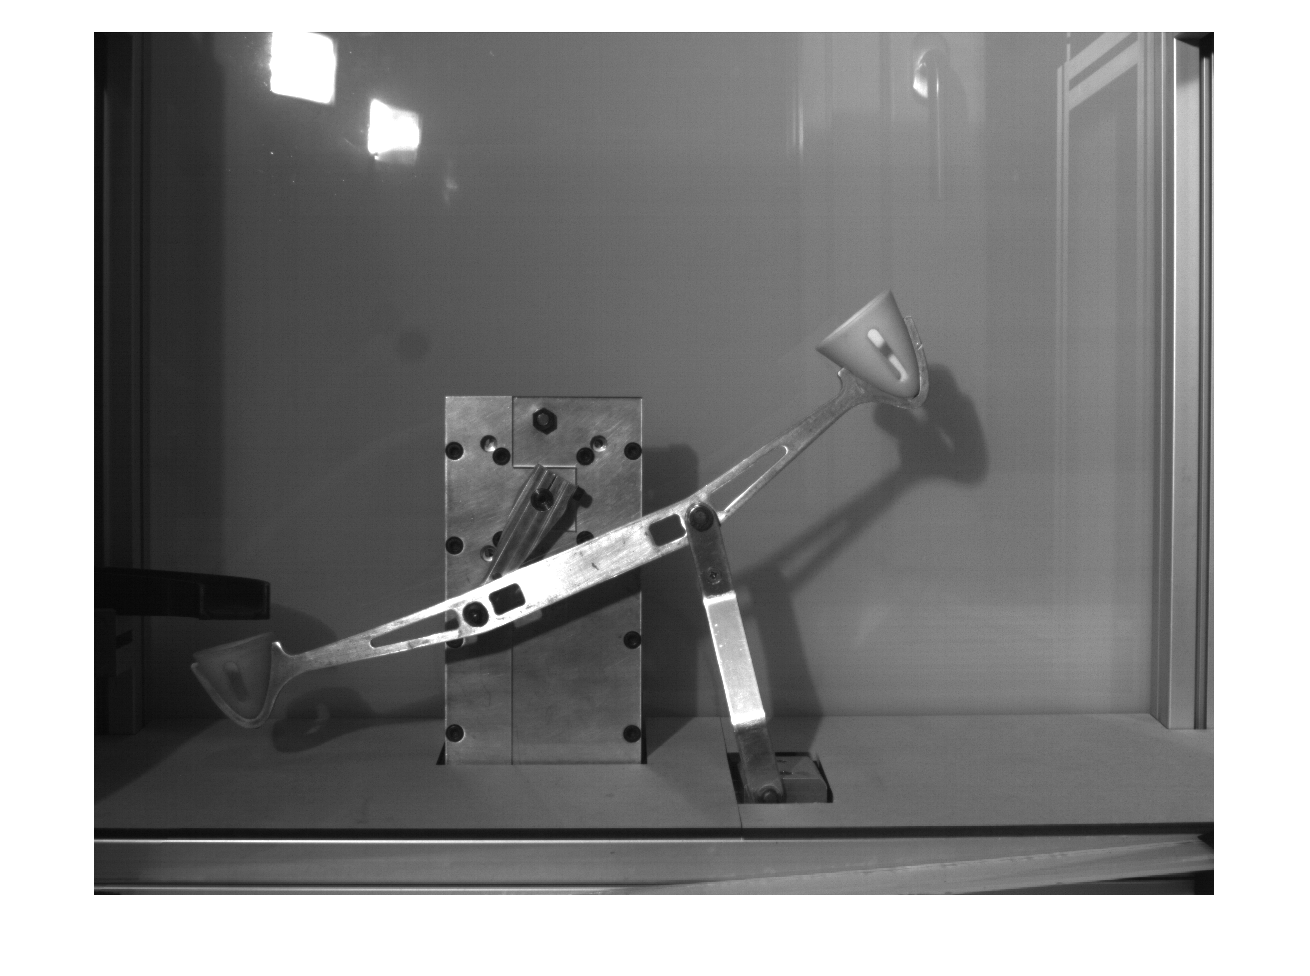

% Gaat wss niet werken, omdat ten eerste ni op dezelfde plaats blijft en
% helemaal op het einde van de video is het ook niet meer zo opvallend als
% in deze frame.
frame = video_data(100,:,:);
frame = squeeze(frame);

figure, imshow(frame)

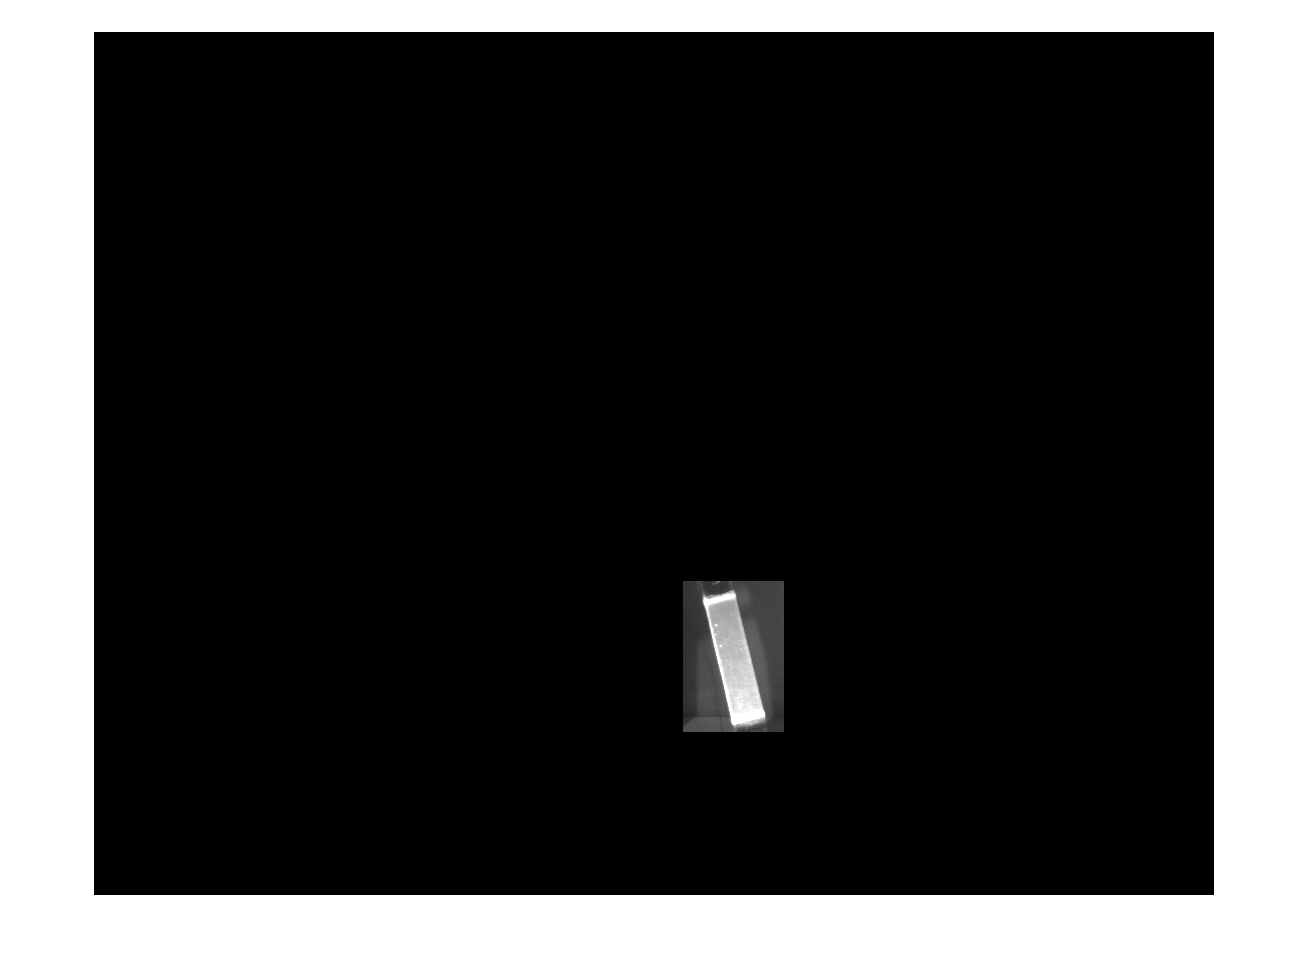

mask = zeros(size(frame));
mask(1100:1400, 1180:1380) = 1;

newIm = uint8(mask) .* frame;
figure, imshow(newIm)

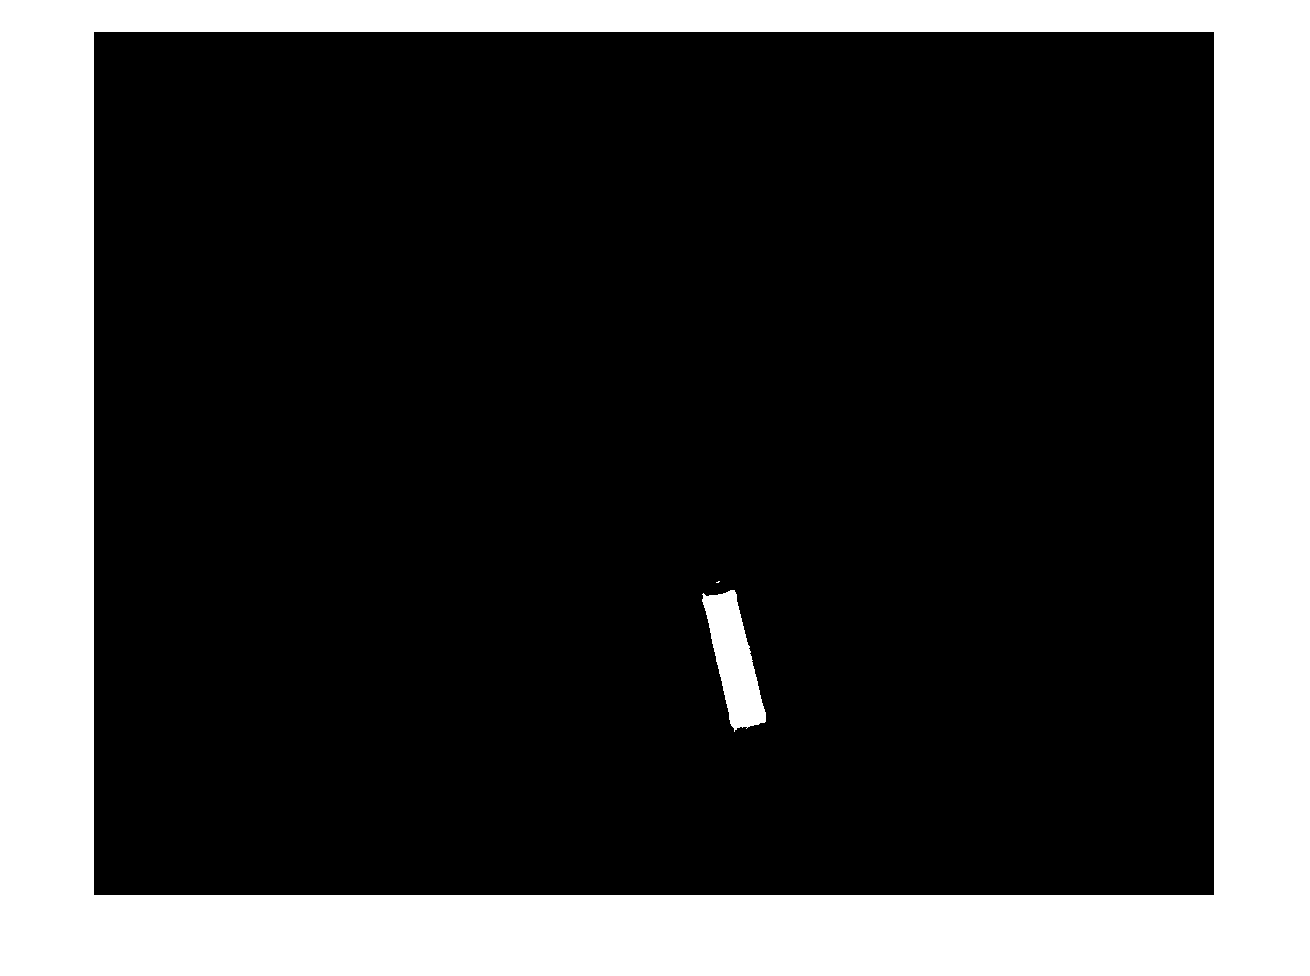

BW = imbinarize(newIm);

figure, imshow(BW)

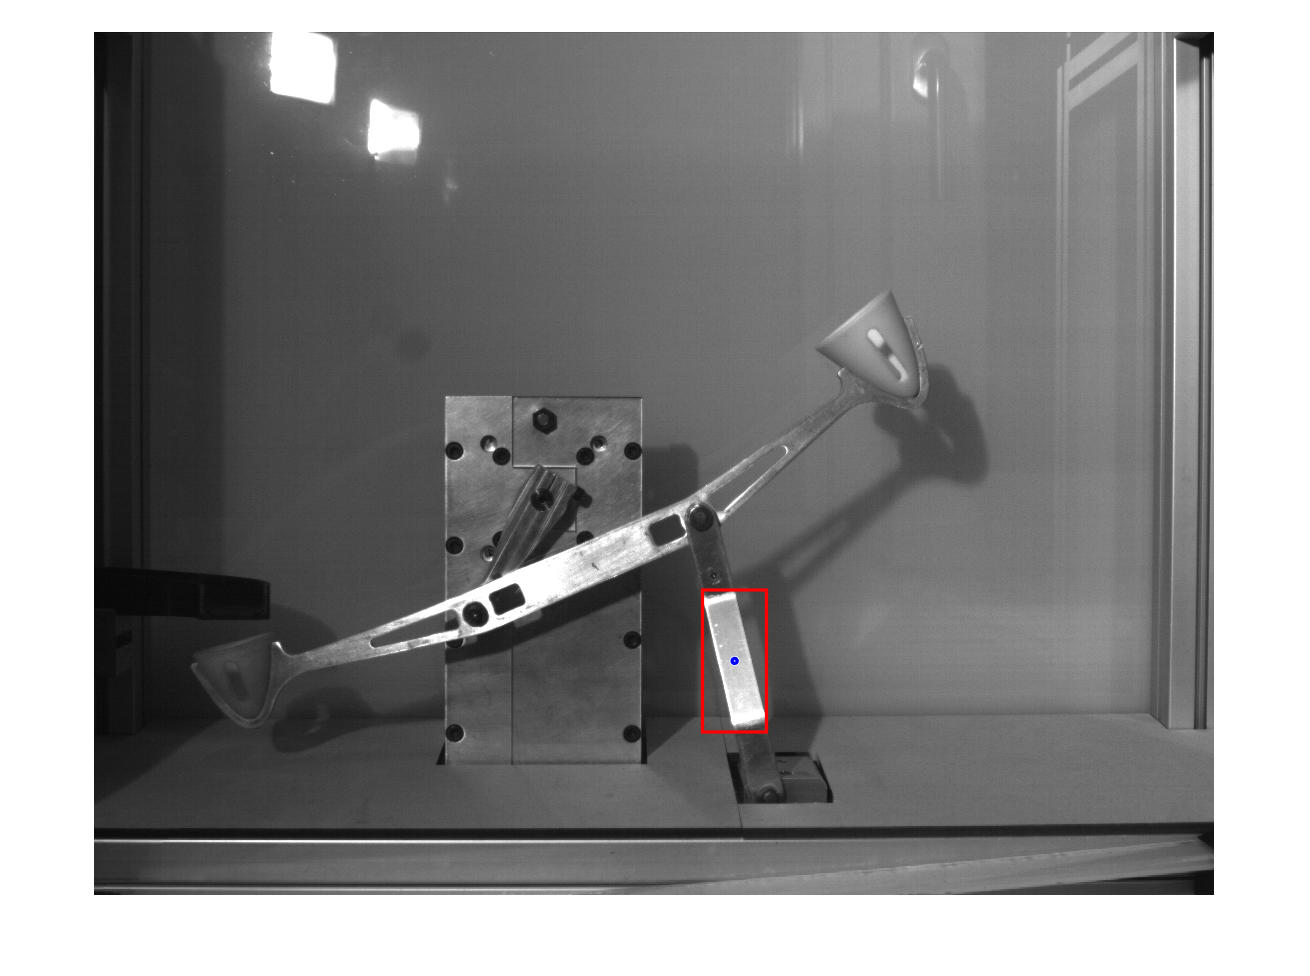



props = regionprops('table',BW, 'BoundingBox', 'Orientation', 'Centroid', 'Area');
figure, imshow(frame);
hold on;

filteredProps = props(props.Area > 500, :);
centroids = filteredProps.Centroid;
boundingBoxes = filteredProps.BoundingBox;
for k = 1:height(filteredProps)
    rectangle('Position', boundingBoxes(k, :), 'EdgeColor', 'r', 'LineWidth', 2);
end
viscircles(centroids, ones(size(centroids, 1), 1) * 5, 'Color', 'b');

hold off;